## Construct 3-phase sampled signal

You could either create a synthetic signal or read a sampled signal from a file:

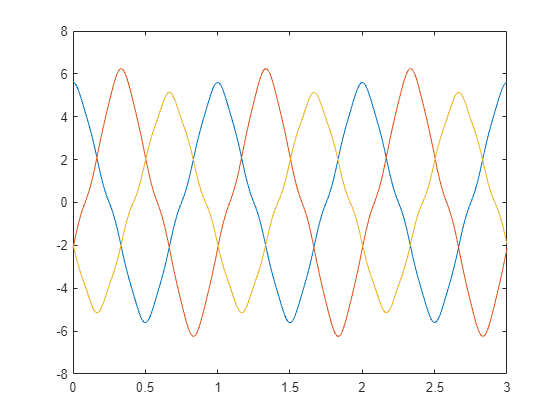

% Fundamental frequency
f = 1;
w = 2 * pi * f;

% Sampling rate in samples/cycle
fs = 1000;

% Signal cycles count
nc = 3;

% Sampled time
t = linspace(0, nc / f, fs * nc + 1);

% Signal sample count
n = length(t);

% Harmonic Signal components
angles = [w * t; w * t - 2 * pi / 3; w * t + 2 * pi / 3];

m = [
    5, 0.5, 0.1; 
    5.5, 0.65, 0.09; 
    4.6, 0.42, 0.12
];

a = m(1,1) * cos(angles(1,:)) + m(1,2) * cos(3 * angles(1,:)) + m(1,3) * cos(7 * angles(1,:));
b = m(2,1) * cos(angles(2,:)) + m(2,2) * cos(3 * angles(2,:)) + m(2,3) * cos(7 * angles(2,:));
c = m(3,1) * cos(angles(3,:)) + m(3,2) * cos(3 * angles(3,:)) + m(3,3) * cos(7 * angles(3,:));

signal = [a; b; c];

plot(t,a);
hold on;
plot(t,b);
plot(t,c);
hold off;

## Curve projection to 2D plane

% We can use PCA for selecting 2 basis vectors for plane of projection
% Make sure signal is nearly centered at the origin
dataCenter = mean(signal, 2)

dataCenter =     0.0019
   -0.0007
   -0.0006


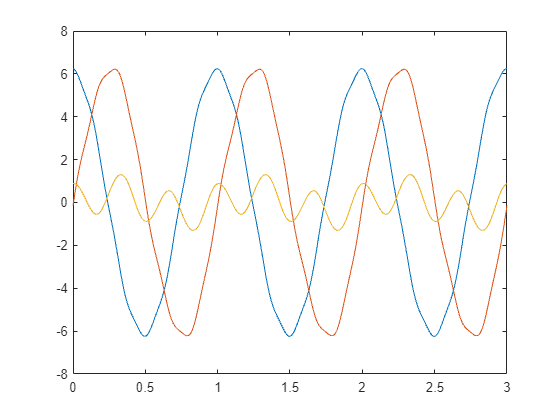

% Use Clarke transform to rotate signal to align (1,1,1) with z-axis
C = sqrt(2/3) * [
    1,          -1/2,       -1/2;
    0,          sqrt(3)/2,  -sqrt(3)/2;
    1/sqrt(2),  1/sqrt(2),  1/sqrt(2)
];

signal = C * signal;

% Rotated signal components
p1 = signal(1, :);
p2 = signal(2, :);
p3 = signal(3, :); % The zero-sequence

plot(t,p1); hold on; plot(t,p2); plot(t,p3); hold off;

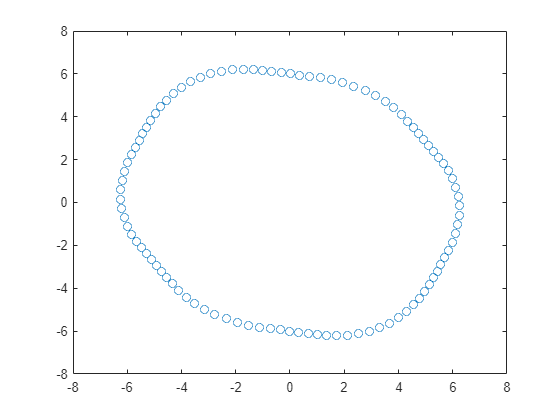

% Now we can take first 2 rotated signal components and try finding the best-fit ellipse
points = [p1; p2];

% We probably should down-sample the signal here, we don't practically need all
% these samples
points = points(:, 1:10:n);
n = size(points, 2);

% Plot points
plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");

## Global Optimization Algorithm

[centerX, centerY, majorTheta, majorLength, minorLength] = fitEllipseGAC(points)

centerX = 8.1124e-04

centerY = -4.1006e-05

majorTheta = -0.8232

majorLength = 6.5740

minorLength = 5.7760

## Draw final results

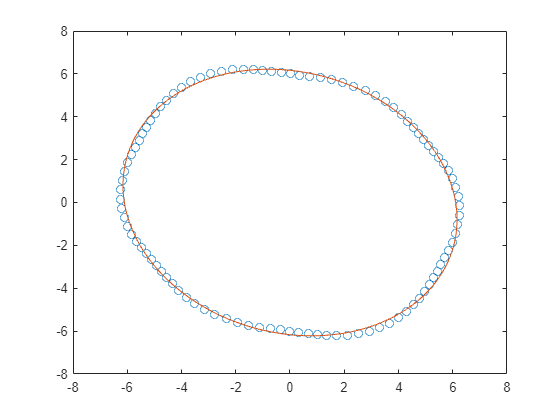

% Ellipse points
ellipsePoints = getEllipsePoints(majorLength, minorLength, majorTheta, centerX, centerY, 361);

% Plot points
plot(points(1,:), points(2,:), "Marker","o", "LineStyle","none");
hold on;
plot(ellipsePoints(1,:), ellipsePoints(2,:), "LineStyle","-");
hold off;

## Extract classification information from ellipse parameters

% Todo: Put sag\swell computations here
% You can use ref "Space Vector Method for Voltage Dips and Swells Analysis"
% Elipse parameters
[shapeIndex, compactness, eccentricity, semilatus_rectum, curvature] = ElipseCharacterization(majorLength, minorLength, ellipsePoints);

shapeIndex

shapeIndex = 0.8786

compactness

compactness = 0.9937

eccentricity

eccentricity = 0.4775

semilatus_rectum

semilatus_rectum = 5.0748

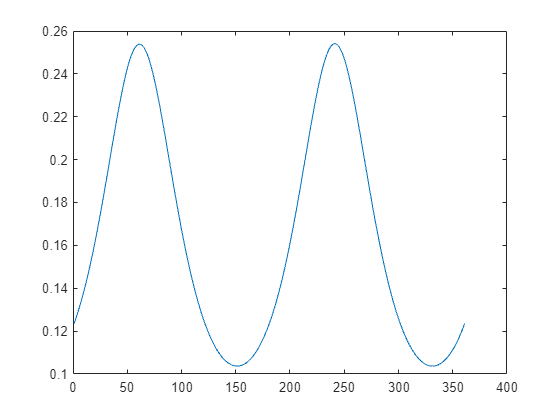

% Plot curvature
figure()
plot(1:length(curvature),curvature)